%% Q2: Experiments with LU factorization
clear; clc; close all;
rng(0);                 

% Given Matrix (data)
A = randn(1000,1000) ./ 1000;
% (a) Compute LU using your routine (no pivoting)
fprintf('(a) Computing LU with my_lu (no pivoting)...\n');

(a) Computing LU with my_lu (no pivoting)...


tic;
[L,U] = my_lu(A);
t_my = toc;
res_my_abs = norm(A - L*U, 'fro');
res_my_rel = res_my_abs / norm(A,'fro');
fprintf('   time = %.3f s | ||A - L*U||_F = %.3e (rel %.3e)\n', t_my, res_my_abs, res_my_rel);

   time = 0.517 s | ||A - L*U||_F = 2.144e-12 (rel 2.145e-12)



% (b) Exact or approximate?
%    -> Check residual; floating point -> approximation
fprintf('(b) Residual indicates approximate factorization in floating point.\n');

(b) Residual indicates approximate factorization in floating point.


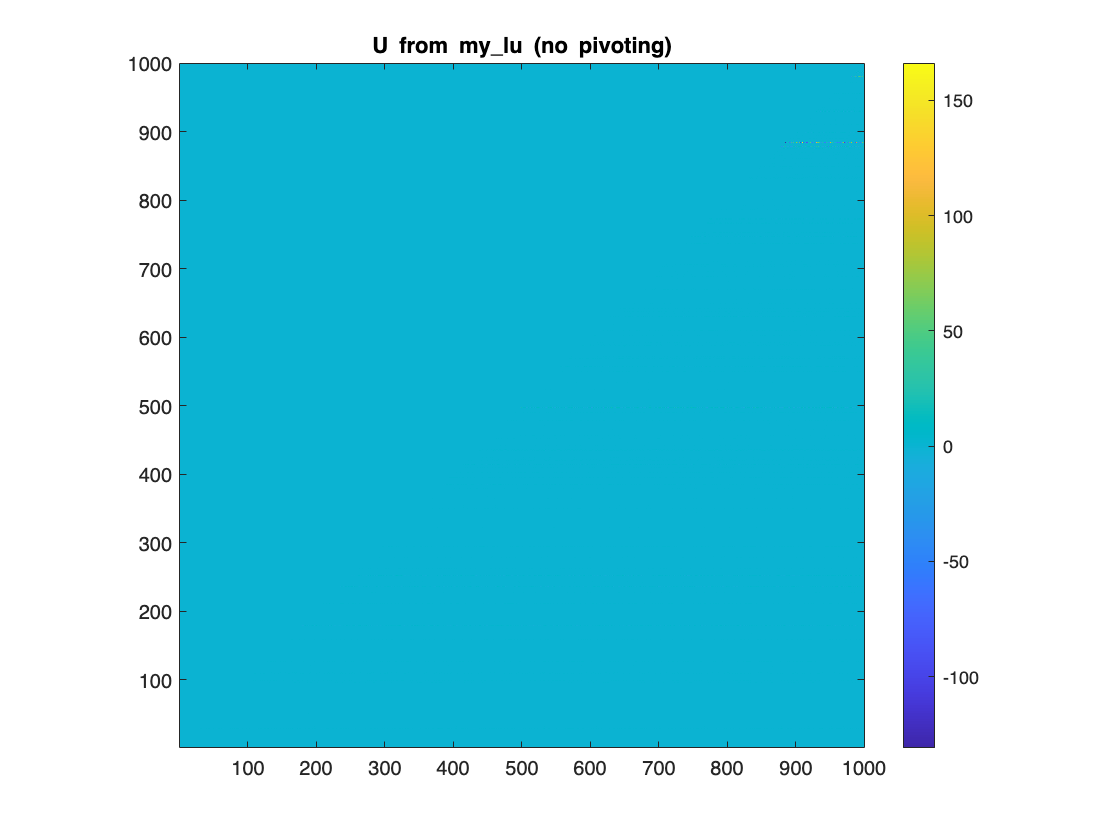


% (c) Visualize factors with imagesc
figure('Name','U (upper triangular)');
imagesc(U); colorbar; axis image; title('U from my\_lu (no pivoting)');
set(gca,'YDir','normal');
saveas(gcf,'U_mylu.png');

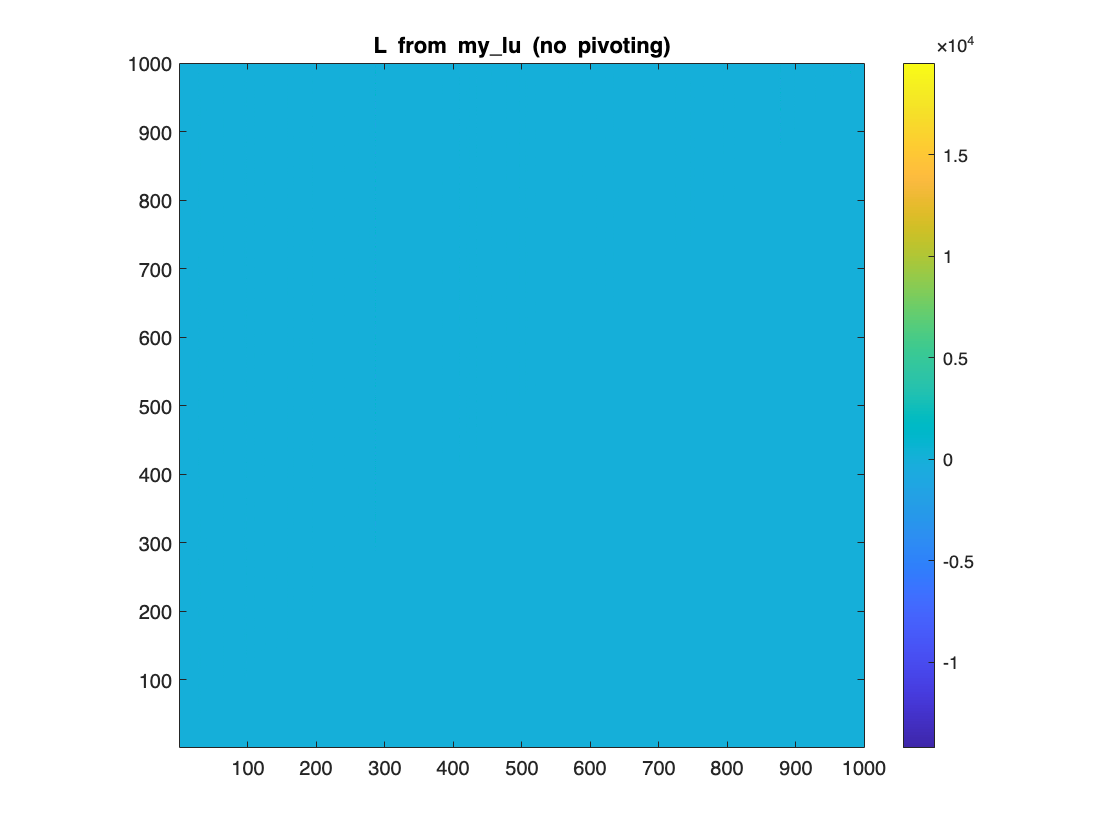


figure('Name','L (unit lower triangular)');
imagesc(L); colorbar; axis image; title('L from my\_lu (no pivoting)');
set(gca,'YDir','normal');
saveas(gcf,'L_mylu.png');


% (d) Compare against MATLAB built-in lu:
% MATLAB computes P*A = Lb*Ub with partial pivoting
fprintf('(d) MATLAB lu with partial pivoting...\n');

(d) MATLAB lu with partial pivoting...


tic;
[Lb,Ub,P] = lu(A);                        
t_matlab = toc;
% Compare residual for MATLAB's factorization: ||P*A - Lb*Ub||
res_mat_abs = norm(P*A - Lb*Ub, 'fro');
res_mat_rel = res_mat_abs / norm(A,'fro');

fprintf('   time = %.3f s | ||P*A - Lb*Ub||_F = %.3e (rel %.3e)\n', t_matlab, res_mat_abs, res_mat_rel);

   time = 0.018 s | ||P*A - Lb*Ub||_F = 5.858e-15 (rel 5.860e-15)



% (e) Construct a 5x5 matrix B that makes no-pivot LU fail (zero first pivot).
%     Nonsingular overall, but a(1,1)=0 -> my_lu errors at Step 1.
B = eye(5);
B([1 2],:) = B([2 1],:);                  % permutation -> B(1,1)=0, det(B)= -1

fprintf('(e) Demonstrate failure on B with no pivoting:\n');

(e) Demonstrate failure on B with no pivoting:


try
    [LB,UB] = my_lu(B);
    fprintf('   Unexpected: my_lu succeeded (should fail on zero pivot)\n');
catch ME
    fprintf('   my_lu failed as expected: %s\n', ME.message);
end

   my_lu failed as expected: Factorization impossible: zero pivot at (1,1).



% MATLAB's pivoting LU succeeds on the same B
[LbB,UbB,PB] = lu(B);
fprintf('   MATLAB lu succeeds: ||PB*B - LbB*UbB||_F = %.3e\n', norm(PB*B - LbB*UbB,'fro'));

   MATLAB lu succeeds: ||PB*B - LbB*UbB||_F = 0.000e+00
